samples = [0.17095947, 0.098724365, -0.02017212, -0.07437134, -0.030883789, -0.0005493164, -0.08590698, -0.19506836, -0.14974976, 0.03137207, 0.16226196, 0.09701538, -0.0776062, -0.11654663, 0.036712646, 0.14630127, 0.04107666, -0.16195679, -0.20635986, -0.051361084, 0.07678223, 0.015014648, -0.14175415, -0.15161133, -0.006164551, 0.08282471, 0.012878418, -0.08276367, -0.06414795, 0.07141113, 0.12164307, 0.029174805, -0.05819702, -0.045074463, 0.0054016113, -0.04147339, -0.1621399, -0.18563843, -0.05718994, 0.038726807, -0.023925781, -0.16983032, -0.19314575, -0.04547119, 0.07333374, 0.029907227, -0.09194946, -0.16363525]

samples =     0.1710    0.0987   -0.0202   -0.0744   -0.0309   -0.0005   -0.0859   -0.1951   -0.1497    0.0314    0.1623    0.0970   -0.0776   -0.1165    0.0367    0.1463    0.0411   -0.1620   -0.2064   -0.0514    0.0768    0.0150   -0.1418   -0.1516   -0.0062    0.0828    0.0129   -0.0828   -0.0641    0.0714    0.1216    0.0292   -0.0582   -0.0451    0.0054   -0.0415   -0.1621   -0.1856   -0.0572    0.0387   -0.0239   -0.1698   -0.1931   -0.0455    0.0733    0.0299   -0.0919   -0.1636



fs = 48000

fs = 48000

sd = 1 / fs

sd = 2.0833e-05


len = length(samples)

len = 48

t = 0:sd:(len - 1) * sd

t = 	1.0e+-3 *

         0    0.0208    0.0417    0.0625    0.0833    0.1042    0.1250    0.1458    0.1667    0.1875    0.2083    0.2292    0.2500    0.2708    0.2917    0.3125    0.3333    0.3542    0.3750    0.3958    0.4167    0.4375    0.4583    0.4792    0.5000    0.5208    0.5417    0.5625    0.5833    0.6042    0.6250    0.6458    0.6667    0.6875    0.7083    0.7292    0.7500    0.7708    0.7917    0.8125    0.8333    0.8542    0.8750    0.8958    0.9167    0.9375    0.9583    0.9792


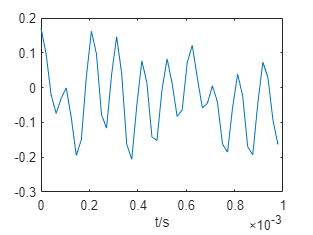


plot(t, samples)
xlabel 't/s'

f = (0:len - 1) * (fs / len)

f =            0        1000        2000        3000        4000        5000        6000        7000        8000        9000       10000       11000       12000       13000       14000       15000       16000       17000       18000       19000       20000       21000       22000       23000       24000       25000       26000       27000       28000       29000       30000       31000       32000       33000       34000       35000       36000       37000       38000       39000       40000       41000       42000       43000       44000       45000       46000       47000


samples_fft = fft(samples)

samples_fft =   -1.5131 + 0.0000i  -0.1515 - 0.3025i   0.2220 - 0.4953i   0.6928 + 0.8521i   0.4339 - 0.0829i   0.3790 - 0.5968i   0.1055 - 0.0643i  -0.4133 - 0.1273i  -0.8351 - 0.1694i   0.3127 + 0.5766i   1.5490 - 2.2449i   0.2676 - 0.1317i   0.2469 - 0.1442i   0.1916 - 0.1622i   0.1783 - 0.1454i   0.1452 - 0.1118i   0.1871 - 0.0684i   0.1543 - 0.0972i   0.2119 - 0.1056i   0.1721 - 0.0631i   0.1857 - 0.0513i   0.1840 - 0.0276i   0.1606 - 0.0247i   0.1909 - 0.0134i   0.1766 + 0.0000i   0.1909 + 0.0134i   0.1606 + 0.0247i   0.1840 + 0.0276i   0.1857 + 0.0513i   0.1721 + 0.0631i   0.2119 + 0.1056i   0.1543 + 0.0972i   0.1871 + 0.0684i   0.1452 + 0.1118i   0.1783 + 0.1454i   0.1916 + 0.1622i   0.2469 + 0.1442i   0.2676 + 0.1317i   1.5490 + 2.2449i   0.3127 - 0.5766i  -0.8351 + 0.1694i  -0.4133 + 0.1273i   0.1055 + 0.0643i   0.3790 + 0.5968i   0.4339 + 0.0829i   0.6928 - 0.8521i   0.2220 + 0.4953i  -0.1515 + 0.3025i


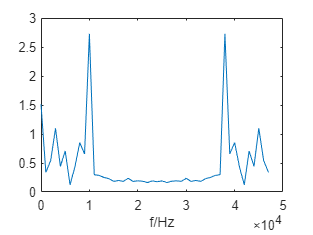


plot(f, abs(samples_fft))
xlabel 'f/Hz'

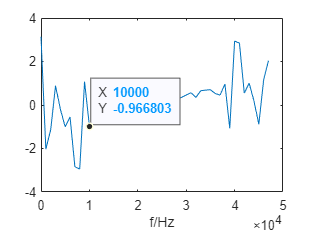

plot(f, angle(samples_fft))
xlabel 'f/Hz'